# Getting the frame

% We will be getting the image frame here and then will apply the algorithm
[intrinsics, color_frame, depth_frame, depth_scaling] = pointcloud_example_humara();

% The point cloud is given as
size(color_frame)

ans =    480   640     3


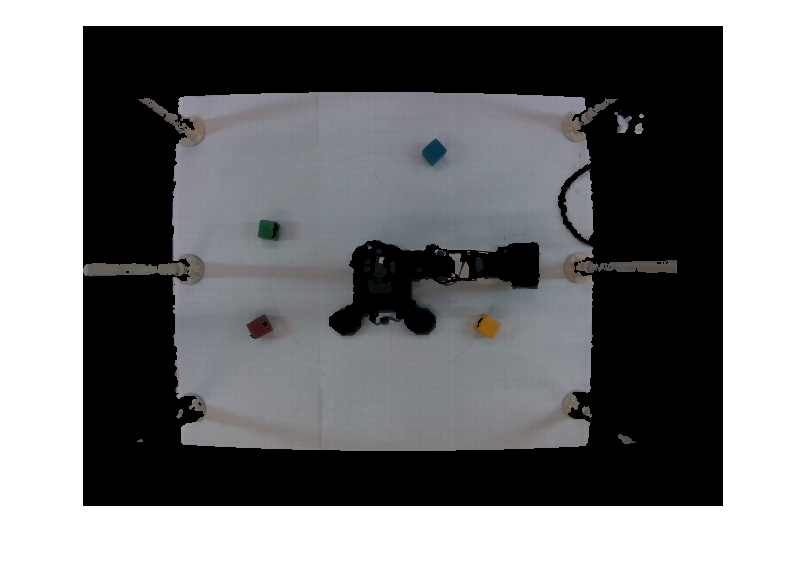

figure;
imshow(color_frame)

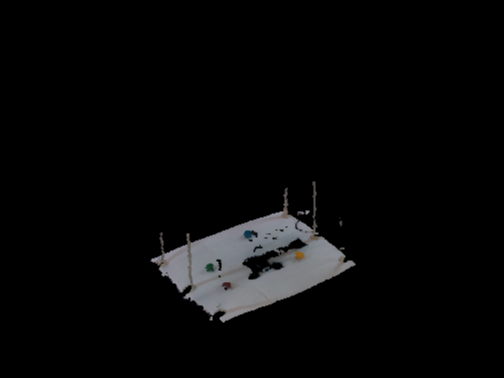

figure;
ptCloud = pcfromdepth(depth_frame, 1/depth_scaling, intrinsics, 'ColorImage', color_frame);
pcshow(ptCloud,'VerticalAxisDir','Down');

# The Algorithm

% The first step of the algorithm is to apply the kmeans clustering and
% increase the number of clusters until we get the desired number of blocks
% completely seperate from other colors/cluster. This will be done using
% the region props which will tell if a region is a block or not
initialClustersNum = 15;
numBlocks = 4;
[numClusters, index, clusters] = getClustersNum(color_frame, initialClustersNum, numBlocks);
numClusters

numClusters = 15

index

index =      3     5     7    14


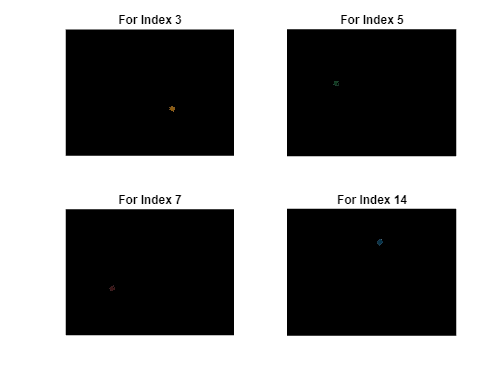

showClusters(index, clusters, color_frame);

% The second step of the algorithm determines that which index represents
% which colored block for example in the above example index 5 reperesents
% the green colored box and index 12 represents the blue colored block. For
% this we will take a pixel at random and see the ratios of colors to
% determine the color of the blocks

centers = getCenters(index, clusters);

colorIndex = zeros([1 4]);
colorCount = 1;
for i = index
    colorIndex(colorCount) = getColor(color_frame, centers(:, colorCount))
    colorCount = colorCount + 1;
end

colorIndex =      4     0     0     0


colorIndex =      4     2     0     0


colorIndex =      4     2     1     0


colorIndex =      4     2     1     3


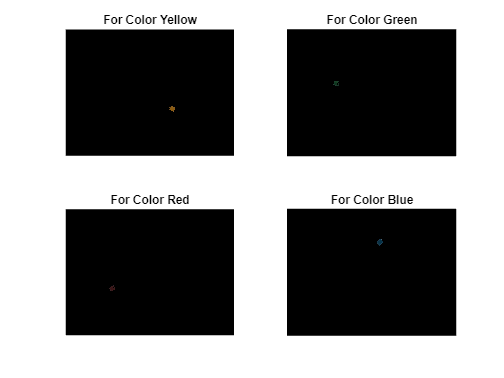

showClusters2(index, clusters, color_frame, colorIndex);

% defining camera parameters
fx = 1400; fy = 1400;
u0 = 932;
% u0 = 1920/2;
v0 = 526;
% v0 = 1080/2;
s = 0;
Intrinsic_trans = [ fx s u0 ; 0 fy v0 ; 0 0 1];
% array to store (x,y) of world coords
Z_c = 660;
% looping over cube (x,y) to transform the coordinates to real world
















% Next step in the algorithm is to identify the corners of the blocks to
% get the position of the block and angle of the block to find the
% orientation of the block

## Yellow Orientation

yellowCorners = getCorners(index(find(colorIndex == 4, 1)), clusters, color_frame);

Error using lab6algo>getCorners
Not enough input arguments.

[yellowx, yellowy, yellowTheta] = getOrientation(yellowCorners.Location)

## Red Orientation

redCorners = getCorners(index(find(colorIndex == 1, 1)), clusters, color_frame);
[redx, redy, redTheta] = getOrientation(redCorners.Location)

## Green Orientation

greenCorners = getCorners(index(find(colorIndex == 2, 1)), clusters, color_frame);
[greenx, greeny, greenTheta] = getOrientation(greenCorners.Location)

## Blue Orientation

blueCorners = getCorners(index(find(colorIndex == 3, 1)), clusters, color_frame);
[bluex, bluey, blueTheta] = getOrientation(blueCorners.Location)

yellowCenter = getCenters(index(find(colorIndex == 4, 1)), clusters);
yellowLoc = 0.0001292.*[246 - round(yellowCenter(2, :)); 294 - round(yellowCenter(1, :))]

yellowLoc =    -0.0080
    0.0152


redCenter = getCenters(index(find(colorIndex == 1, 1)), clusters);
redLoc = 0.0001292.*[246 - round(redCenter(2, :)); 294 - round(redCenter(1, :))]

redLoc =    -0.0076
   -0.0137


greenCenter = getCenters(index(find(colorIndex == 2, 1)), clusters);
greenLoc = 0.0001292.*[246 - round(greenCenter(2, :)); 294 - round(greenCenter(1, :))]

greenLoc =     0.0044
    0.0150


blueCenter = getCenters(index(find(colorIndex == 3, 1)), clusters);
blueLoc = 0.0001292.*[246 - round(blueCenter(2, :)); 294 - round(blueCenter(1, :))]

blueLoc =     0.0147
   -0.0068


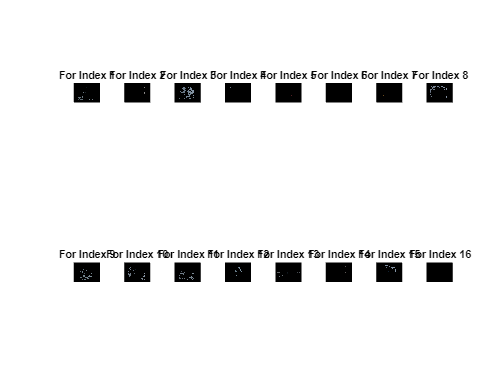


clusters = getClusters(color_frame, 18);
showClusters(1:1:16, clusters, color_frame);

Now we can use the centre of the arm as Pr, and find the distance of the blocks from the centre of the arm. This will be used later for the pick and place algorithm.The X,Y coordinates of the corner of the yellow block given by the code are (117, 220) while the intel realsense application shows these coordinates to be (540, 590)). In the present setting the difference bwteeen real and actual coordinates is (540-cameracoordinatex, 590 - cameracoordinatey). The coordinates for the centre of the arm in the application are (960, 490) therefore the coordinates according to our code will be (960 - 423, 490 - 370) => (537, 120).

sizeperblock;
numblockstocentre;


one = im2double(clusters == 5);
area = regionprops("table", one, "Area", "Circularity", "ConvexArea", "EquivDiameter", "FilledArea", "Perimeter", "Solidity", "BoundingBox")

area = 1×8 table
    Area              BoundingBox               ConvexArea    Circularity    FilledArea    EquivDiameter    Solidity    Perimeter
    ____    ________________________________    __________    ___________    __________    _____________    ________    _________

    273     388.5    293.5       22       22       281          0.91841         273           18.644        0.97153      61.118  


area = getBBarea(area.BoundingBox)

area = 484

one = im2double(clusters == 6);
area = regionprops("table", one, "Area", "Circularity", "ConvexArea", "EquivDiameter", "FilledArea", "Perimeter", "Solidity", "BoundingBox")

area = 1×8 table
    Area              BoundingBox               ConvexArea    Circularity    FilledArea    EquivDiameter    Solidity    Perimeter
    ____    ________________________________    __________    ___________    __________    _____________    ________    _________

    240     168.5    201.5       20       20       278          0.72015         242           17.481        0.86331      64.714  


area = getBBarea(area.BoundingBox)

area = 400

one = im2double(clusters == 7);
area = regionprops("table", one, "Area", "Circularity", "ConvexArea", "EquivDiameter", "FilledArea", "Perimeter", "Solidity", "BoundingBox")

area = 1×8 table
    Area              BoundingBox               ConvexArea    Circularity    FilledArea    EquivDiameter    Solidity    Perimeter
    ____    ________________________________    __________    ___________    __________    _____________    ________    _________

    378     161.5    294.5       24       22       400          0.94805         378           21.938         0.945       70.784  


area = getBBarea(area.BoundingBox)

area = 528

one = im2double(clusters == 14);
area = regionprops("table", one, "Area", "Circularity", "ConvexArea","EquivDiameter", "FilledArea", "Perimeter", "Solidity", "BoundingBox")

area = 1×8 table
    Area            BoundingBox             ConvexArea    Circularity    FilledArea    EquivDiameter    Solidity     Perimeter
    ____    ____________________________    __________    ___________    __________    _____________    _________    _________

    1083    46.5    73.5     547     345    1.5548e+05      21.446          1107          37.134        0.0069654     25.191  


area = getBBarea(area.BoundingBox)

area = 188715

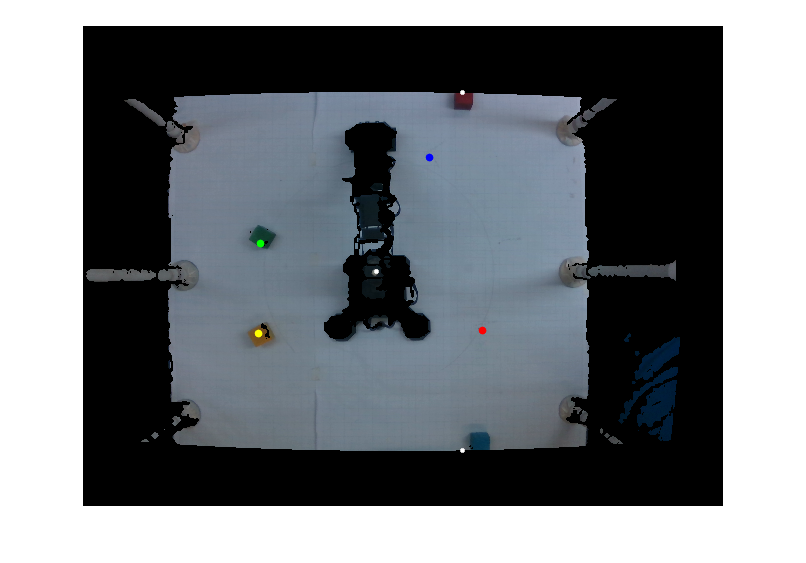

figure;
im = imshow(color_frame);
hold on
plot(176, 308,".", MarkerSize=20, Color='y');
plot(400, 305,".", MarkerSize=20, Color='r');
plot(178, 218,".", MarkerSize=20, Color='g');
plot(347, 132,".", MarkerSize=20, Color='b');
plot(294, 246,".", MarkerSize=10, Color='w');
% rectangle('Position', redarea.BoundingBox, 'EdgeColor', 'red');
plot(380, 67,".", MarkerSize=10, Color='w');
plot(380, 425,".", MarkerSize=10, Color='w');

# Functions

function [num, index, clusters] = getClustersNum(img, initialClustersNum, numBlocks)
    count = initialClustersNum;
    index = zeros([1 numBlocks]);
    while true
        clusters = getClusters(img, count);
        [blocks, indices] = getBlocksNum(clusters, count);
        if (blocks == numBlocks)
            break;
        else
            count = count+1;
        end
    end
    num = count;
    indexCount = 1;
    for i = 1:length(indices)
        if (indices(i) == 1)
            index(indexCount) = i;
            indexCount = indexCount + 1;
        end
    end
end



function vec = getClusters(img, numColors)
    img = rgb2lab(img);
    ab = img(:,:,2:3);
    ab = im2single(ab);
    vec= imsegkmeans(ab,numColors,NumAttempts=1);
end



function [num, blocks] = getBlocksNum(clusters, numClusters)
    count = 0;
    blocks = zeros([1 numClusters]);
    for i = 1:numClusters
        one = im2double(clusters == i);
        area = regionprops("table", one, "Area", "Circularity", "BoundingBox");
        BB = getBBarea(area.BoundingBox);

%         if (area.Area < 500 && area.Area > 300 && area.Circularity > 0.7 && area.Circularity < 1)
%             count = count + 1;
%             blocks(i) = 1;
%         end
        if (area.Area < 450 && area.Area > 240) %pehle 400, 270  && BB > 400 && BB < 700
            count = count + 1;
            blocks(i) = 1;
        end
    end
    num = count;
end



function centers = getCenters(index, clusters)
    centers = zeros([2 length(index)]);

    for i = 1:length(index)
        one = im2double(clusters == index(i));
        area = regionprops("table", one,"Centroid");
        centers(:, i) = area.Centroid;
    end

end



function showClusters(index, clusters, color_frame)
    figure;
    for i = 1:length(index)
        one = im2double(clusters == index(i));
        color_frame = im2double(color_frame);
        [r, g, b] = imsplit(color_frame);
        framer = r.*one;
        frameg = g.*one;
        frameb = b.*one;
    
        frame = cat(3, framer, frameg, frameb);
        subplot(2, length(index)/2, i);
        imshow(frame);
        title("For Index "+index(i));

    end
end



function showClusters2(index, clusters, color_frame, colors)
    figure;
    colorList = ["Red", "Green", "Blue", "Yellow"];
    for i = 1:length(index)
        one = im2double(clusters == index(i));
        color_frame = im2double(color_frame);
        [r, g, b] = imsplit(color_frame);
        framer = r.*one;
        frameg = g.*one;
        frameb = b.*one;
    
        frame = cat(3, framer, frameg, frameb);
        subplot(2, length(index)/2, i);
        imshow(frame);
        title("For Color "+colorList(colors(i)));

    end
end




function val = getColor(img, center)
    c = transpose(center);
%     one = im2double(clusters == num);
%     [row, col] = find(one==1, 1);
%     [row, col] = transpose(center);
    col = round(c(1));
    row = round(c(2));
    [r, g, b] = imsplit(img);
    r = double(r(row, col));
    g = double(g(row, col));
    b = double(b(row, col));
    
    % 1 = red
    % 2 = green
    % 3 = blue
    % 4 = yellow

    if (r/b > 1 && g/b > 1)
        val = 4;
    elseif (g/r > 1 && g/b > 1)
        val = 2;
    elseif (b/r > 1 && b/g > 1)
        val = 3;
    elseif (r/g > 1 && r/b > 1)
        val = 1;
    else
        val = 0;
    end
    
    
end



function corners = getCorners(num, clusters, color_frame)
    one = im2double(clusters == num);
    points = detectHarrisFeatures(one);
    color_frame = im2double(color_frame);
    [r, g, b] = imsplit(color_frame);
    framer = r.*one;
    frameg = g.*one;
    frameb = b.*one;

    frame = cat(3, framer, frameg, frameb);
%     figure;
%     imshow(frame); 
%     hold on 
    corners = points.selectStrongest()
%     corners.Location
%     plot(corners);
%     hold off
end



function [x, y, theta] = getOrientation(corners)
    distarr = 1:3;
    temp = [1 2; 1 3; 2 3];
    distarr(1) = distance(corners(1, :), corners(2, :));
    distarr(2) = distance(corners(1, :), corners(3, :));
    distarr(3) = distance(corners(2, :), corners(3, :));
    maxdist = max(distarr);
    ind = find(distarr == maxdist);
    corners(temp(ind, 1), :);
    corners(temp(ind, 2), :);
    [x, y] = getMidPoint(corners(temp(ind, 1), :), corners(temp(ind, 2), :));
%     x = x-420;
%     y = y-320;
    temp2 = 1:2;
    temp2count = 1;
    for i = 1:length(distarr)
        if (ind ~= i)
            temp2(temp2count) = i;
            temp2count = temp2count + 1;
        end
    end
    angles = 1:2;
    angleCount = 1;
    for i = temp2
        p1 = corners(temp(i, 1), :);
        p2 = corners(temp(i, 2), :);
        angles(angleCount) = rad2deg(atan2((p2(2) - p1(2)),(p2(1) - p1(1))));
        angleCount = angleCount + 1;
    end
    theta = min(angles);
end



function area = getBBarea(boundingBox)
    area = boundingBox(3) * boundingBox(4);
end


function dist = distance(p1, p2)
    x = (p2(1) - p1(1))^2;
    y = (p2(2) - p1(2))^2;
    dist = sqrt(x + y);
end



function [x, y] = getMidPoint(p1, p2)
    x = (p2(1) + p1(1))/2;
    y = (p2(2) + p1(2))/2; 
end

function determineIntrinsics()
    % Make Pipeline object to manage streaming
    pipe = realsense.pipeline();
    
    % Start streaming on an arbitrary camera with default settings
    profile = pipe.start();

    % Extract the color stream
    color_stream = profile.get_stream(realsense.stream.color).as('video_stream_profile');
    
    % Get and display the intrinsics
    color_intrinsics = color_stream.get_intrinsics()

end